#### Tanner Graph 

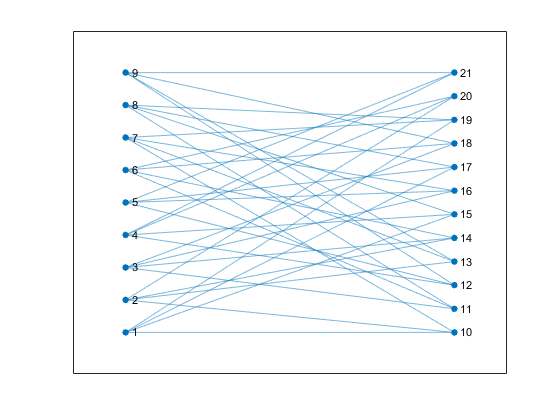

close all;
clear all;
%load Hmatrix.mat

H=[1 0 0 0 0 1 0 1 0 1 0 0;
    1 0 0 1 1 0 0 0 0 0 1 0;
    0 1 0 0 1 0 1 0 1 0 0 0;
    0 0 1 0 0 1 0 0 0 0 1 1;
    0 0 1 0 0 0 1 1 0 0 0 1;
    0 1 0 0 1 0 0 0 1 0 1 0;
    1 0 0 1 0 0 1 0 0 1 0 0;
    0 1 0 0 0 1 0 1 0 1 0 0;
    0 0 1 1 0 0 0 0 1 0 0 1];

[m, n] = size(H);

big_a = [zeros(m,m), H;
    H', zeros(n,n)];
g = graph(big_a);
% Plot
h = plot(g);
% Formatting
h.XData(1:m) = 1;
h.XData((m+1):end) = 2;
h.YData(1:m) = linspace(0,1,m);
h.YData((m+1):end) = linspace(0,1,n);

Message Passing Algorithm for BEC HDD: (9,12) regular LDPC code:

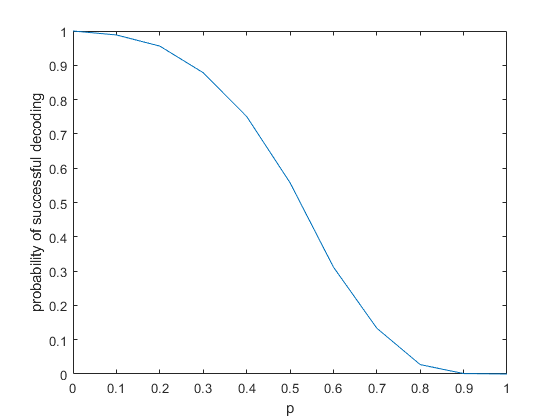

clear vars
close all

 H=[1 0 0 0 0 1 0 1 0 1 0 0;
     1 0 0 1 1 0 0 0 0 0 1 0;
     0 1 0 0 1 0 1 0 1 0 0 0;
     0 0 1 0 0 1 0 0 0 0 1 1;
     0 0 1 0 0 0 1 1 0 0 0 1;
     0 1 0 0 1 0 0 0 1 0 1 0;
     1 0 0 1 0 0 1 0 0 1 0 0;
     0 1 0 0 0 1 0 1 0 1 0 0;
     0 0 1 1 0 0 0 0 1 0 0 1];
%load Hmatrix.mat [H]
[m, n] = size(H);

a=zeros(1,11);
f=1;

pError = 0:0.1:1;
for p = pError
    err=0;
    crr=0;
    for Nsim=1:10000
        transmitted_message = zeros(1,n);
        q=transmitted_message.';
        received_message = BinaryEraserChannel(transmitted_message, p);
        %decoding part
      

        d_c = Evaluate_Degree(H(1,:));
        d_v = Evaluate_Degree(H(:,1));

        c_n = zeros(m, sum(H(1,:))+d_c);
        v_n = zeros(n, 1+d_v);

       
        %Initializing V_N's and C_N's Matrix
        for i = 1:n
            v_n(i,1) = received_message(i);
            v_n(i,2:1+d_v) = find(H(:,i))';
        end

        for i = 1:m
            c_n(i,1:d_c) = find(H(i,:));
        end

        it = 0;
        it_Max =50;

        while it < it_Max

            check=v_n(:,1);

            it = it + 1;

            % VNs->CNs

            for i=1:m
                for j=1+d_c:d_c+d_c
                    c_n(i,j)=v_n(c_n(i,j-d_c),1);
                end
            end
            %c_n

            

            % CNs->VNs

            g=0;
            for j=1:m
                %for i=1:d_c
                h=c_n(j,1+d_c:2*d_c);
                if sum(h==-1)==1
                    x=find(h==-1);
                    y=c_n(j,1+d_c:2*d_c);
                    y(1,x)=1;
                    if mod(sum(y),2)~=0
                        y(1,x)=0;
                    end
                    v_n(c_n(j,x),1)=y(1,x);
                elseif sum(h==-1)==0
                    g=g+1;
                end
                %end
            end
            if g==m
                break;
            end

            %v_n

            
            if check==v_n(:,1)
                break;
            end
        end
        d=v_n(:,1);
        if d==q
            crr=crr+1;
        else
            err=err+1;
        end
    end
    %crr/10000
    a(1,f)=crr/10000;
    f=f+1;
end
%a
plot(pError,a)
xlabel('p')
ylabel('probability of successful decoding')

Calculating Degree

function d = Evaluate_Degree(vector)
d = sum(vector);
end

BEC CHANNEL

function receiver = BinaryEraserChannel(vector, p)
receiver = zeros(1, length(vector));
counter = 1;
for i = vector
    if rand() <= p
        receiver(counter) = -1;
    else
        receiver(counter) = i;
    end
    counter = counter + 1;
end
end
